# Differential Encoder Description

clear all;
close all;
clc; 

Define x[n]:

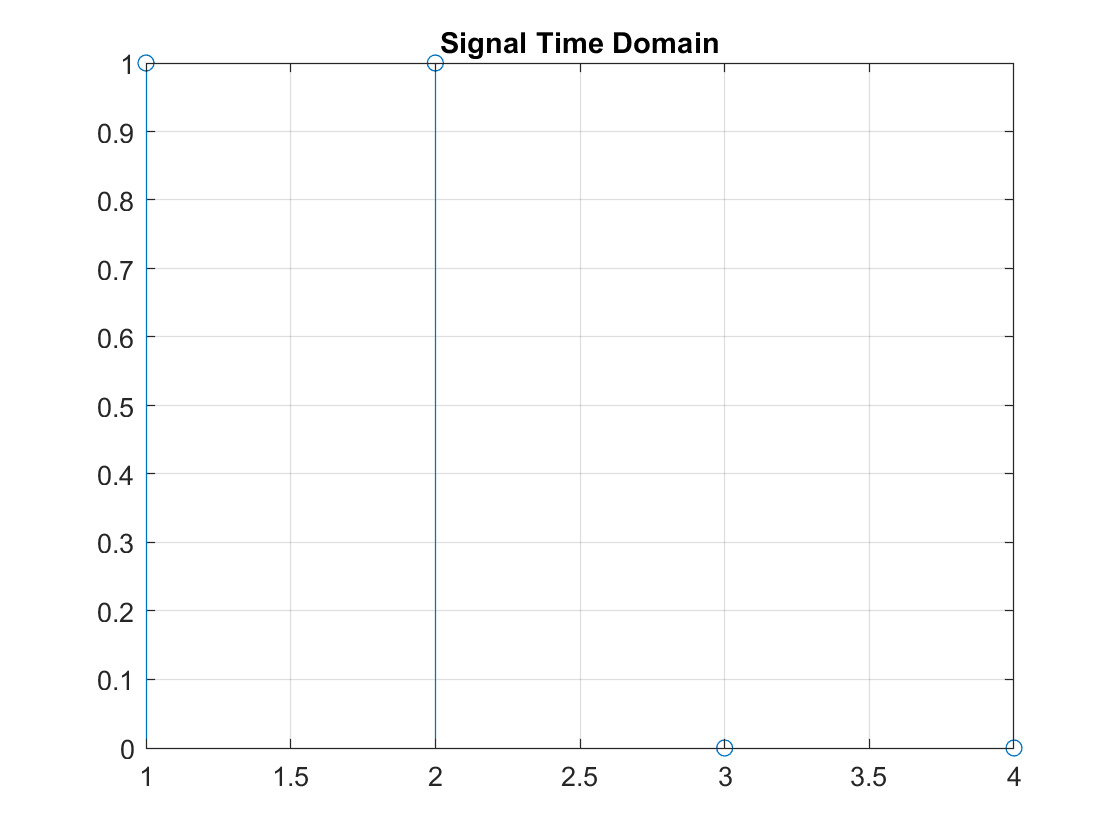

n=[0:1:7]; %signal length 8
n=n/(2*pi);% so we have 8 samples in one period 
x_n=[1 1 0 0];
X_z=[1 1 0 0]; % 1*z^0 + 1z^-1
figure(1);
stem(x_n);
title('Signal Time Domain');
grid on;

#### 1T.) Signal Flow Diagramm 

(first order filter)

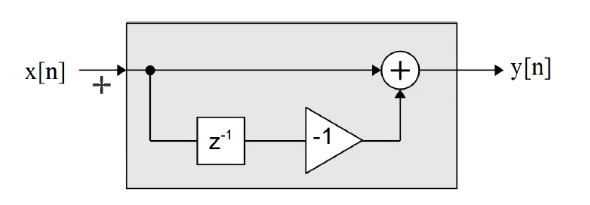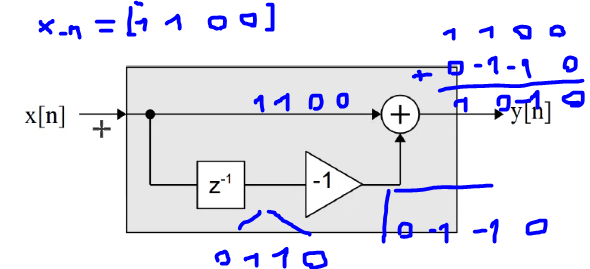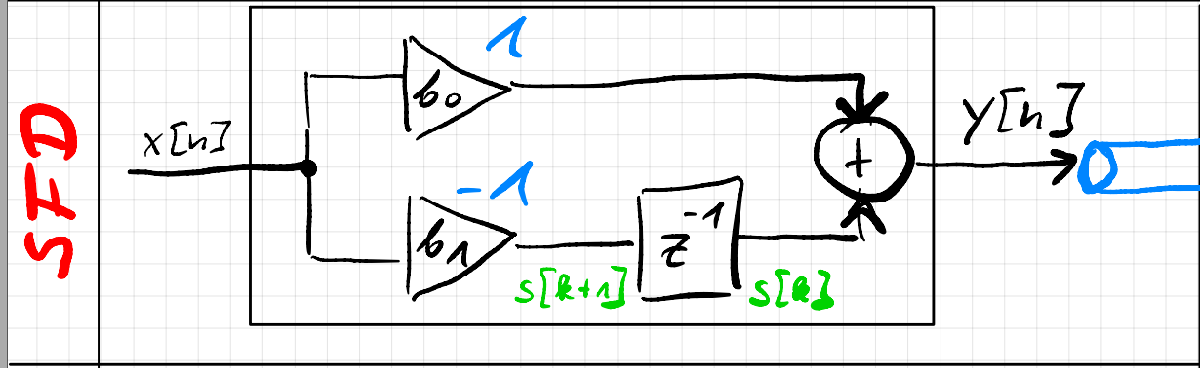

#### 2T.) Difference Equation

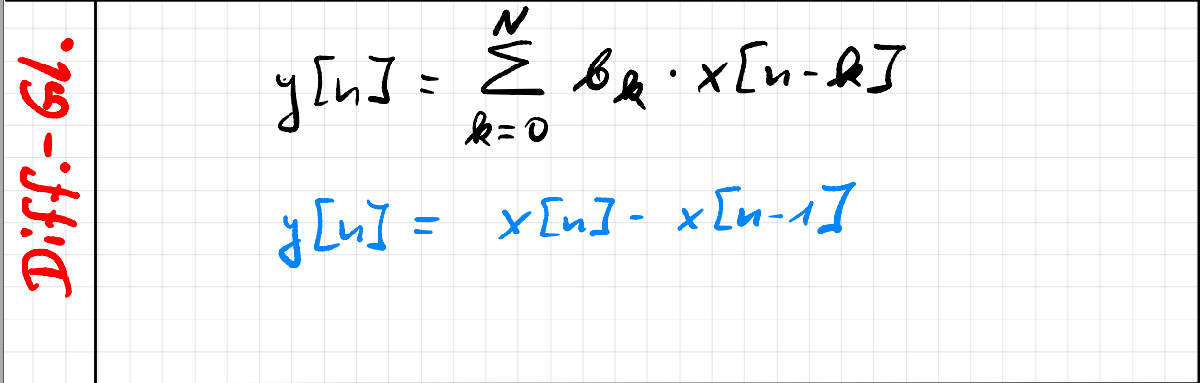

y[n]=x[n]*z^(-1)*(-1)+x[n]

y[n]=x[n-1]*(-1)+x[n]

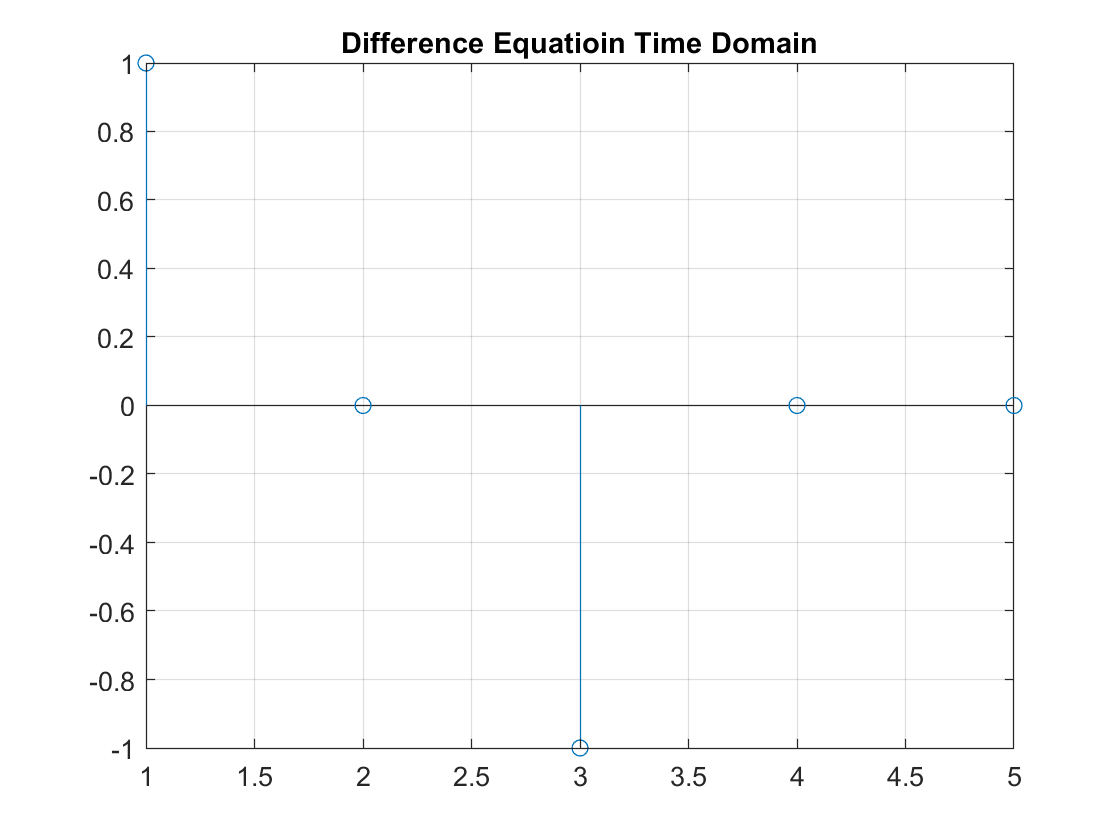

delay=[0 1]; %define delay
y_1n=-1*conv(x_n,delay); %delay by one sample, multiply by -1
x_n(numel(y_1n)) = 0; %adjust length of x_n
y_n=x_n+y_1n; %do addition
stem(y_n); %plot everything
title('Difference Equatioin Time Domain');
grid on;

#### 3T.) Impulse Response (aka. Transferfunction ?)

(endliche eingabe endliche ausgabe = FIR)

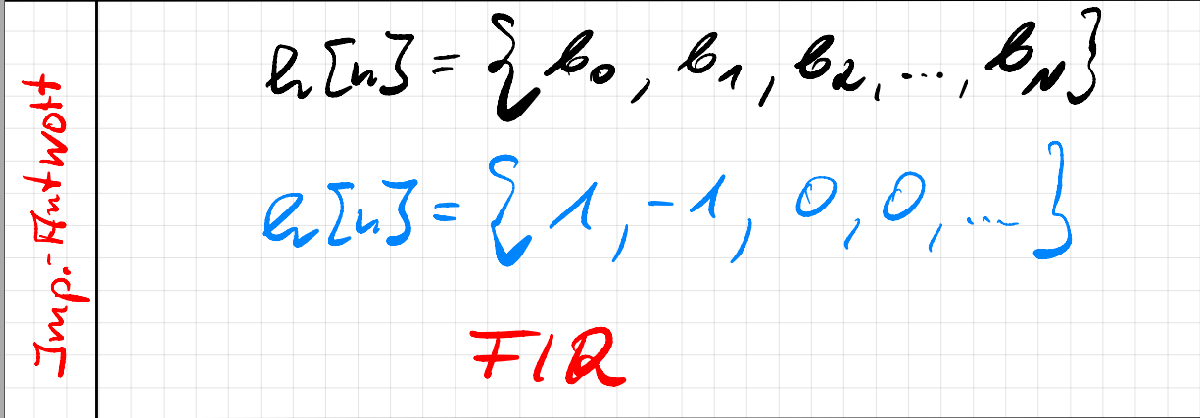

y[n]=x[n]*z^(-1)*(-1)+x[n]

y[n]=x[n]*(z^-1*-1+1)

y[n]/x[n]=z^-1*-1+1

h[n]=(-1z^-1+1)/1

h[n]=[1 -1]

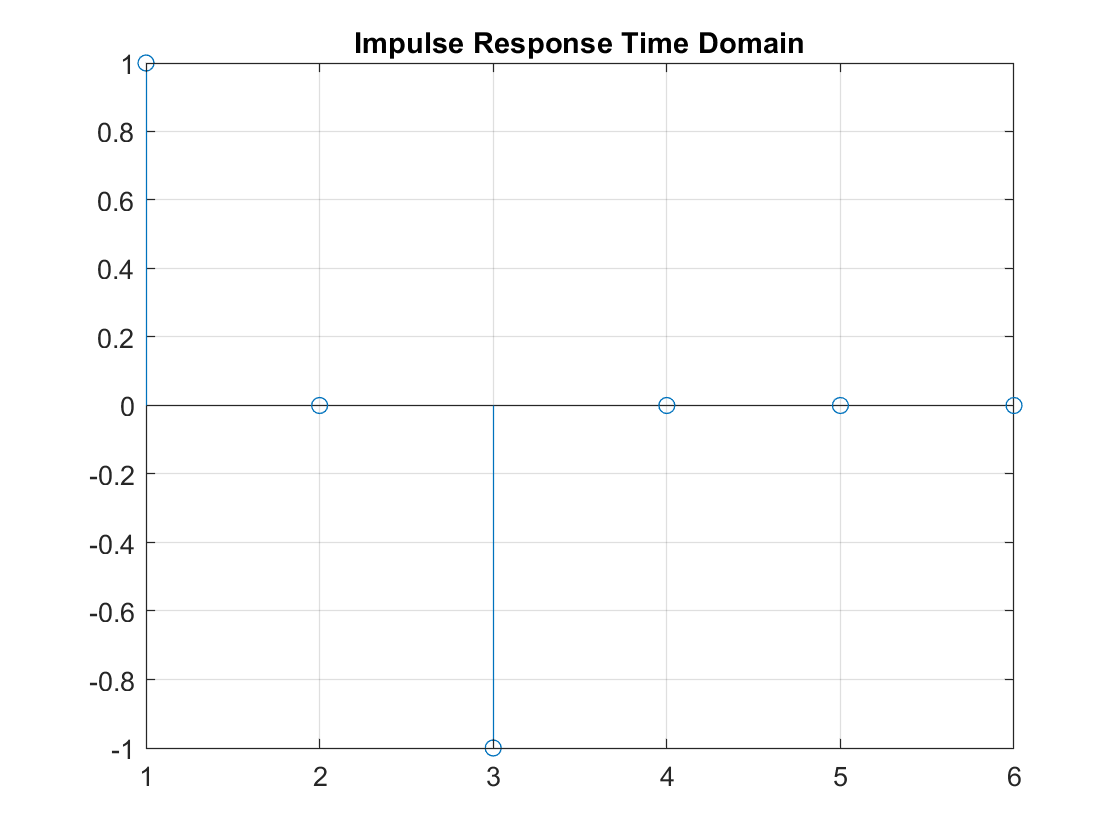

h_n=[1 -1];
y_n=conv(x_n,h_n);
stem(y_n);
title('Impulse Response Time Domain');
grid on;

#### 1F.) Transferfunction

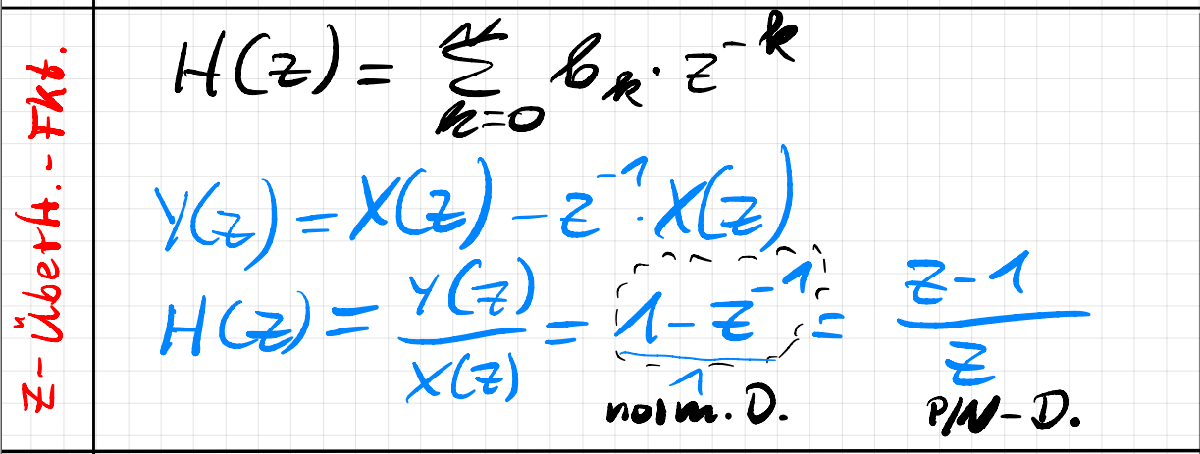

H[z]=(-1z^-1+1)/1

H_z=[1 -1 0 0];
Y_z=H_z.*X_z

Y_z =      1    -1     0     0


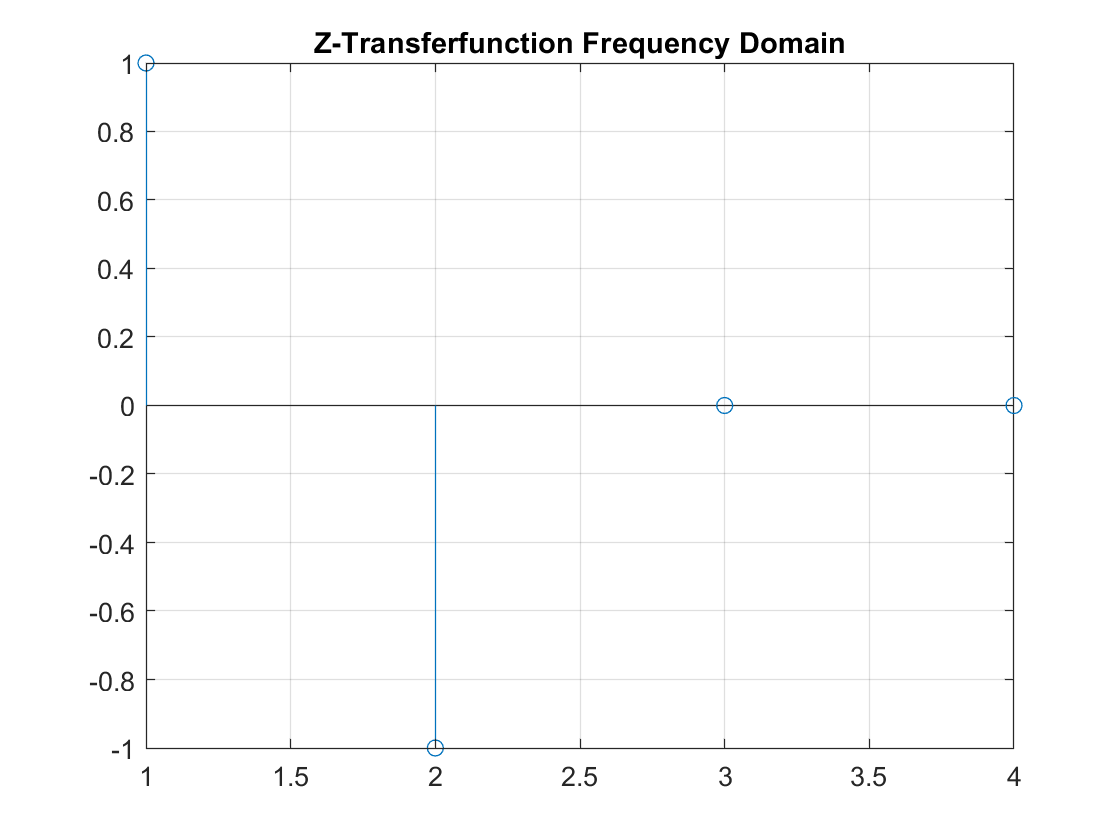

stem(Y_z)
title('Z-Transferfunction Frequency Domain');
% stem(ifft(Y_z))
grid on;

#### 3F.) Pole Zero Plot

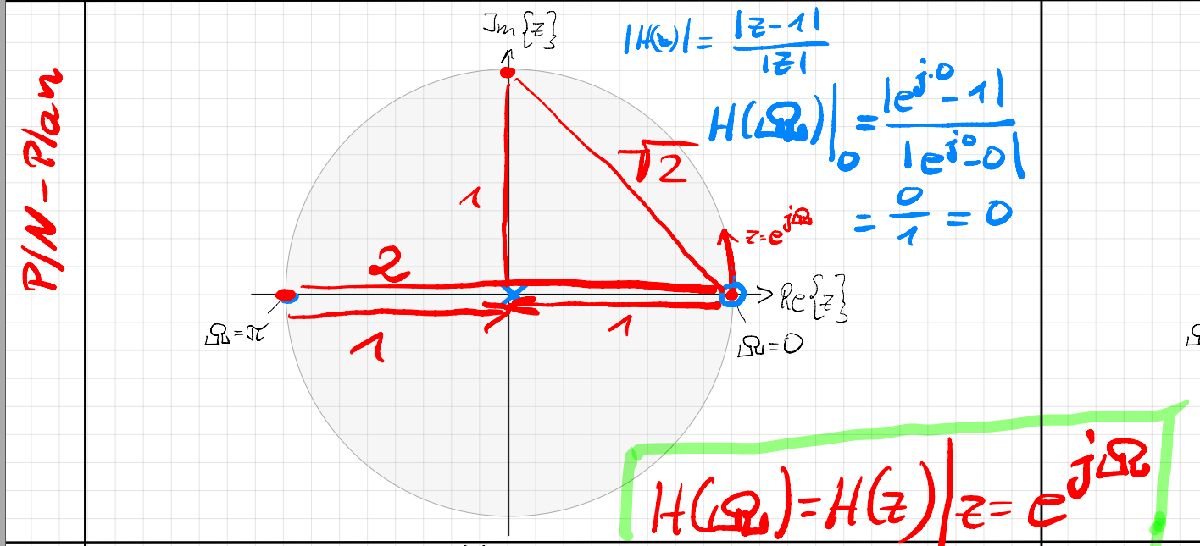

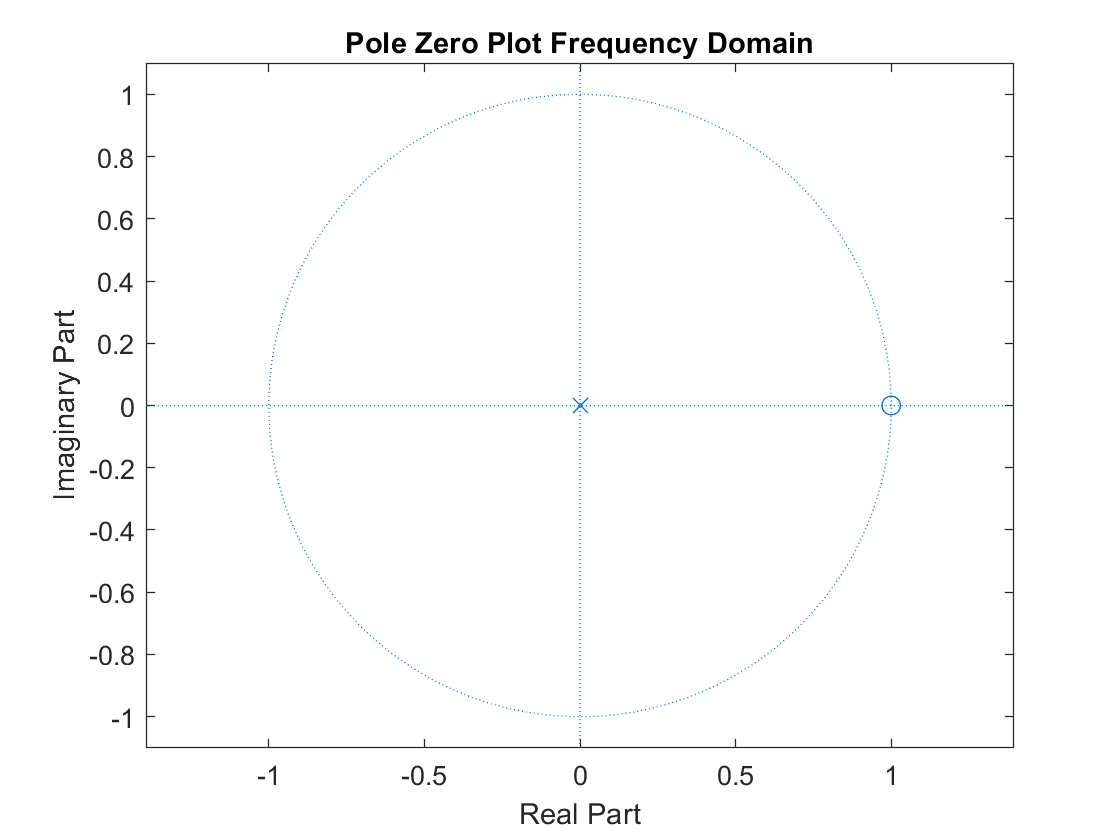

zplane(h_n)
title('Pole Zero Plot Frequency Domain');

#### 2F.) Frequency Response

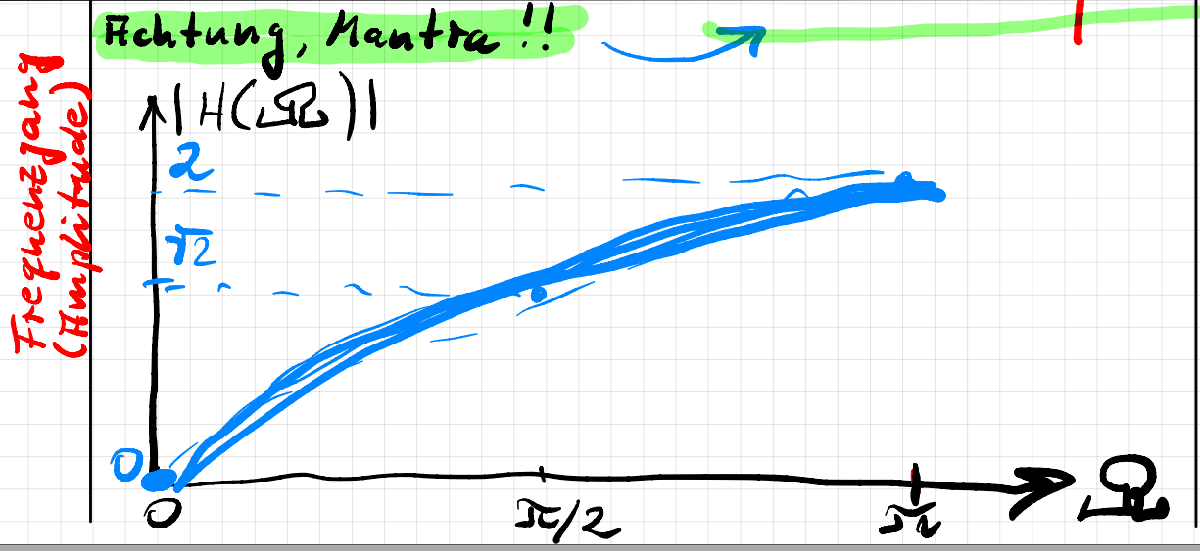

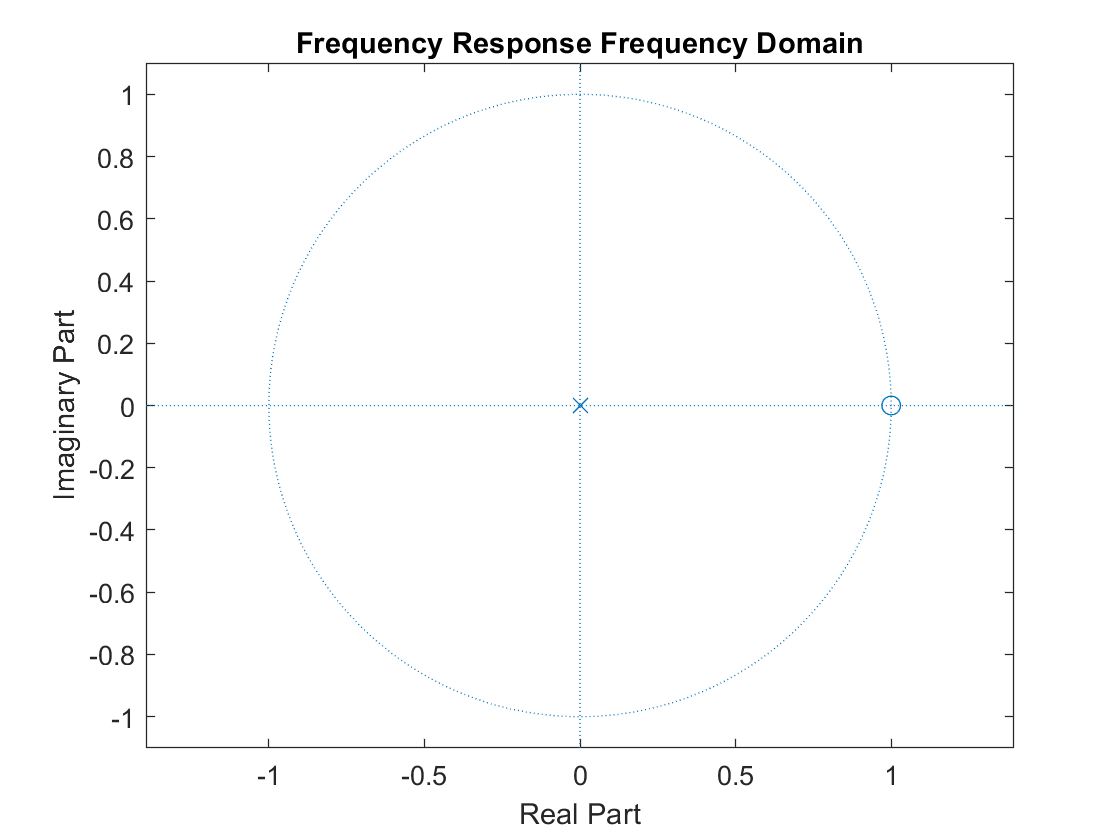

title('Frequency Response Frequency Domain');

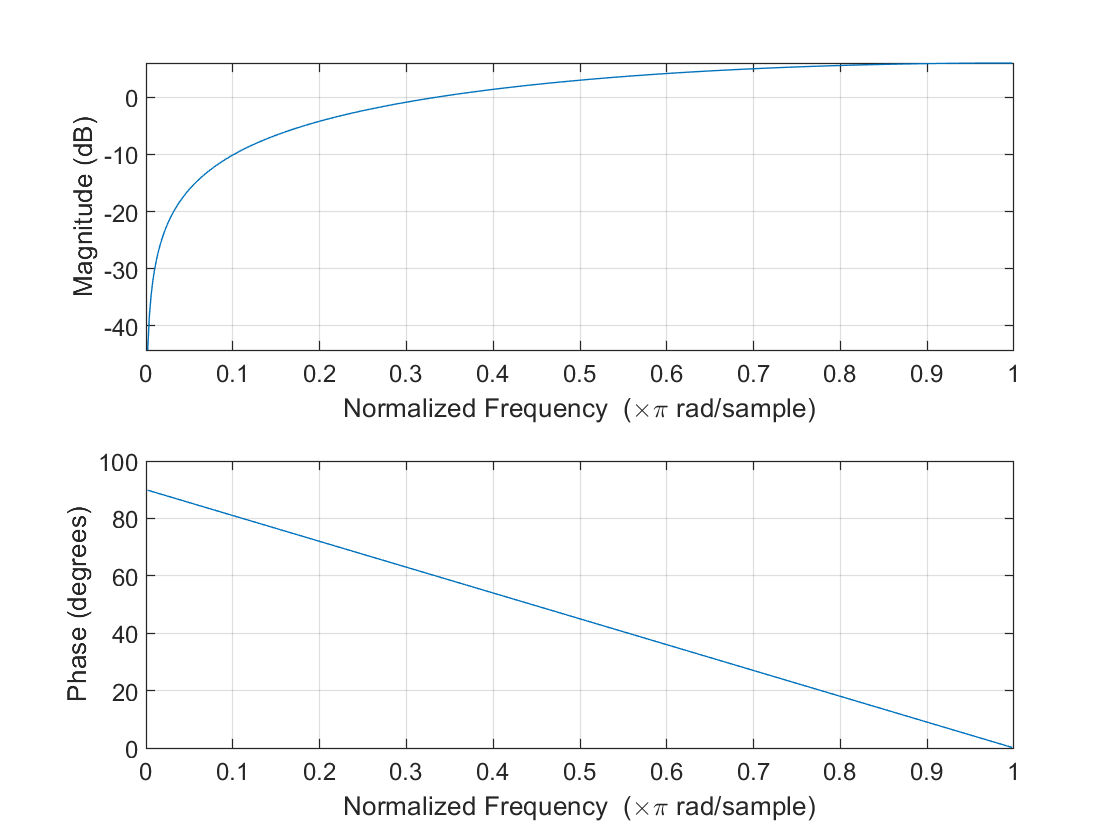

freqz(h_n)

#### Questions:

- where is the difference between H_z and h_n? 

- how can i realize the multiplication in the frequenzy domain y-z=h-z*x-z?

- How can i multiply in the Z-Domain and then transfer it back ?

# Differential Decoder Description